# **SISTEMAS DE CONTROL DISCRETO                                **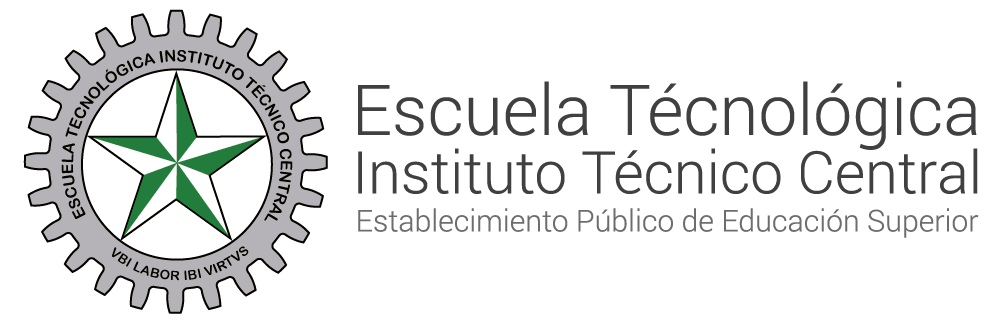

# PROPIEDADES DE LA TRANSFROMADA Z

**Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO**

**Coautor: JUAN DAVID QUINTERO MISE **

**INGENIERIA MECATRÓNICA**

**OBJETIVO**

Al finalizar esta sesión, los estudiantes serán capaces de comprender y aplicar las propiedades clave de la Transformada Z en el análisis de señales y sistemas discretos. Aprenderán a representar y trabajar con conceptos como el escalón unitario, la rampa y el desplazamiento temporal en el dominio Z. Además, dominarán el uso del teorema de suma y resta, así como el teorema de la multiplicación, para resolver problemas y simplificar cálculos en sistemas discretos.

## Paso a Paso

**ESCALÓN UNITARIO.**

¿QUE ES EL ESCALÓN UNITARIO?

El escalón unitario es como el botón de "play" que le damos a un sistema. Es una señal que comienza en un valor de 1 en un momento específico  y se mantiene en 1 todo el tiempo después de ese instante. Es útil para representar cuando un sistema empieza a funcionar y se mantiene activo de manera continua.

Se define como:

Demostración:

para cualquier funcion y(k) = 1

partiendo de la ecuacion que representa la suma de una serie geometrica.


$$\sum_{k=0}^n r^{k\;\;} =\frac{r^{n+1} -1}{r-1}$$


1) Con la definicion de transformada z 

2) Con la definicion de transformada z las llevaremos a la suma de una serie geometrica.

= 

3) Desarrollo

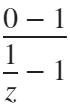

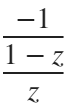


$$\sum_{k=0}^n {{\left(z^{-1} \right)}^k }$$

$$\frac{-z}{1-z}$$



$$\sum_{k=0}^n {{\left(z^{-1} \right)}^k }$$

$$\frac{-z}{1-z}*\frac{-1}{-1}$$


4) Obtenemos la definicion de escalon unitario.

**Ejemplo**

5) Grafica de la función

% Acontinuación encontrara la grafica de respuesta al escalón unitario
% tendra usted la capacidad de manipular tres variables diferentes:

% eje_X = podra mover el rango de tiempo discreto aumentando y
%         disminuyendolo a su elección
% EU    = valor del escalón unitario a su elección
% TS    = tiempo entre cada muestra 
% NOTA  = Se recomienda que el rango del eje x sea mayor al ts

clear; 
close all;

eje_x=22

eje_x = 22

EU=   12

EU = 12

Ts=   8

Ts = 8

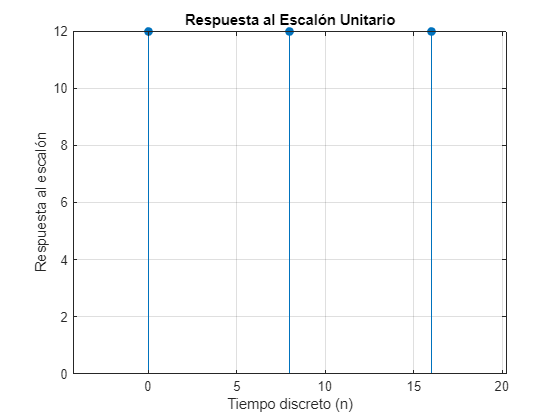

syms z n;

figure(1);

% Escalón
respuesta_escalon = iztrans(EU*z / (z - 1), z, n);

n_values = 0:Ts:eje_x;
respuesta_escalon_values = subs(respuesta_escalon, n, n_values);

% Graficar la respuesta al escalón
stem(n_values, double(respuesta_escalon_values), 'filled');
xlabel('Tiempo discreto (n)');
ylabel('Respuesta al escalón');
title('Respuesta al Escalón Unitario');
grid on;

**RAMPA**

Una rampa en un sistema discreto es una señal que crece de forma lineal con el tiempo en pasos discretos, definida como:

Representa una secuencia de valores 0,1,2,3,... Que inicia en cero y aumenta uniformemente, usada comúnmente para analizar la respuesta de sistemas discretos a entradas crecientes de manera lineal.

Demostración:

Interpretación de la función rampa unitaria en el dominio de z

Organizamos para arrancar en el primer punto de la gráfica…

A X(z) le restamos z^-1X(z) para que la respuesta se ajuste a una función conocida

Reorganizamos, obteniendo el comportamiento de la respuesta unitaria multiplicada por z^-1

Tal que obtenemos la siguiente ecuación para la función rampa:


$${X{\left(z\right)}*1-z}^{-1} \;\;=z^{-1} \frac{1}{\left.{\left(1-z\right.}^{-1} \right)}$$
       


$$R´\left(Z\right)=\frac{{Tz}^{-1} }{{\left(\frac{z-1}{z}\right)}^2 }$$


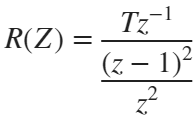

        RAMPA      

**Ejemplo**

5) Grafica de la función

% Acontinuación encontrara la grafica de rampa
% tendra usted la capacidad de manipular 2 variables diferentes:

% eje_X1 = podra mover el rango de tiempo discreto aumentando y
%         disminuyendolo a su elección
% TS1   = tiempo entre cada muestra 
% NOTA  = Se recomienda el el rango del eje x1 sea mayor al ts1

eje_x1=71

eje_x1 = 71

TS1 =  3

TS1 = 3

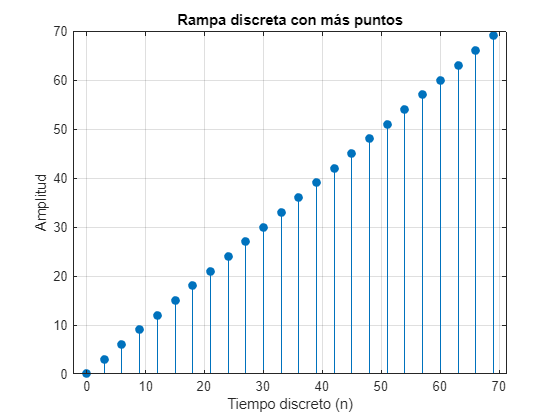

syms z n;

% Parámetros
t = 1;

% Ecuación de la rampa en el dominio discreto
R_z = t * z / (z - 1)^2;

% Transformada inversa de la ecuación de la rampa 
rampa_n = iztrans(R_z, z, n);

% Tiempo de análisis y tiempo de muestreo definido en el vector n_values 
n_values = 0:TS1:eje_x1;
rampa_values = subs(rampa_n, n, n_values); 

% Graficar
figure(2); 
stem(n_values, double(rampa_values), 'filled');
xlabel('Tiempo discreto (n)');
ylabel('Amplitud');
title('Rampa discreta con más puntos');
grid on;

**DESPLAZAMIENTO**

El **desplazamiento en sistemas discretos** es cuando una señal se mueve en el tiempo, ya sea hacia adelante (retraso) o hacia atrás (adelanto). Esto significa que los valores de la señal cambian su posición en el eje del tiempo. Por ejemplo, si una señal original es x[n], un desplazamiento hacia adelante sería x[n−k], donde la señal aparece más tarde, y un desplazamiento hacia atrás sería x[n+k], donde la señal aparecera antes.

Por ejemplo:

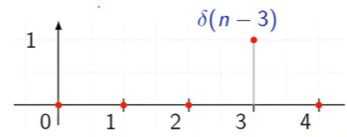

Este ejemplo de aca unicamente nos dice, que  hay un valor atrasado 3 muestras. Es decir no comienza desde 0, sino desde 3.

Viendolo en dominio Z.

Nos da la idea que el resto de valores en y unicamente existe el valor en 

Entonces la transformada  z 

A su vez representa un X(k)

                   el valor atrasado 3 muestras.

segundo ejemplo

             su X(k) 

 aca claramente estamos hablando en termios de muestras 

Complemento a la demostración.

1) Cambio de variable

2) Reemplazamos

   Aca observamos que basicamente es la definición de transfromada z

osea de la manera:

Ejemplo:

Con la ecuacion de la rampa.

% Acontinuación encontrara la grafica de desplazamiento
% tendra usted la capacidad de manipular 4 variables diferentes:

% eje_X2 = podra mover el rango de tiempo discreto aumentando y
%          disminuyendolo a su elección
% TS2    = tiempo entre cada muestra 
% AD     = adelanto de la señal
% ATR    = atraso de la señal

eje_x2= 30

eje_x2 = 30

TS2 =  3

TS2 = 3

AD =  7

AD = 7

ATR =  7

ATR = 7

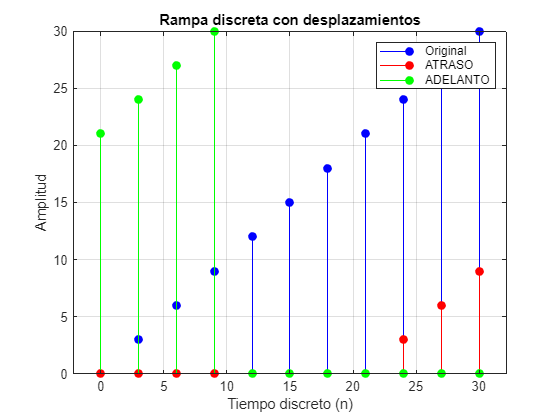

syms z n;

% Parámetros
t = 1; % Factor de escala

% Ecuación de la rampa en z
R_z = t * z / (z - 1)^2;

% Transformada inversa
rampa_n = iztrans(R_z, z, n);

% Vector
n_values = 0:TS2:eje_x2; 
rampa_values = subs(rampa_n, n, n_values);

% Desplazamientos
k_forward = ATR; % ATRASO
rampa_forward_values = [zeros(1, k_forward), double(rampa_values(1:end-k_forward))];

k_backward = AD; % ADELANTO
rampa_backward_values = [double(rampa_values(k_backward+1:end)), zeros(1, k_backward)];

% Graficar
figure(3); 
stem(n_values, double(rampa_values), 'b', 'filled', 'DisplayName', 'Original'); hold on;
stem(n_values, rampa_forward_values, 'r', 'filled', 'DisplayName', 'ATRASO'); 
stem(n_values, rampa_backward_values, 'g', 'filled', 'DisplayName', 'ADELANTO'); 
xlabel('Tiempo discreto (n)');
ylabel('Amplitud');
title('Rampa discreta con desplazamientos');
legend;
grid on;

**TEOREMA DE LA SUMA Y RESTA**

Explica que la transformada Z de la suma o resta de dos señales en el tiempo discreto es igual a la suma o resta de sus transformadas Z individuales. Esto significa que, si tienes dos señales x1[n] Y x2[n] sus transformadas Z, X1(z) y X2(z), se combinan directamente como:

DEMOSTRACIÓN:

como ejemplo tendremos dos funciones 

1) Escribir la transformada Z de la suma de las señales

   Su transformada z sera:

2) Separar la suma dentro de la serie (simplemente es usar la propiedad distributiva de la suma)

3) Hallamos la transformada z individual

Por lo tanto 

X

Para la resta

Si seguimos el mismo razonamiento

   

1) Separamos nuevamente los terminos

2) Como lo mostramos anteriormente, esto resultara en:

X

% Acontinuación encontrara la grafica de teorema de suma y resta
% tendra usted la capacidad de manipular 4 variables diferentes:

% eje_X3 = podra mover el rango de tiempo discreto aumentando y
%          disminuyendolo a su elección
% TS3    = tiempo entre cada muestra 

eje_x3=20

eje_x3 = 20

ts3=   12

ts3 = 12




bt = 15;
syms z n;

x1_n = n;         
x2_n = 2*n + 1;    

% Transformadas Z individuales
X1_z = ztrans(x1_n, n, z); 
X2_z = ztrans(x2_n, n, z); 
sum_separadas = X1_z + X2_z; % Suma de las transformadas Z individuales

% Suma de señales
x_sum_n = x1_n + x2_n;
sum_directa = ztrans(x_sum_n, n, z); % Transformada Z de la suma

% Transformada inversa de Z
sum_separadas_time = iztrans(sum_separadas, z, n);
sum_directa_time = iztrans(sum_directa, z, n);

n_values = 0:ts3:eje_x3; % Valores de tiempo discreto
sum_separadas_values = subs(sum_separadas_time, n, n_values); 
sum_directa_values = subs(sum_directa_time, n, n_values);

disp('Transformada Z de x1[n]:');

Transformada Z de x1[n]:


disp(X1_z);

$$\frac{z}{{\left(z-1\right)}^{2}}$$


disp('Transformada Z de x2[n]:');

Transformada Z de x2[n]:


disp(X2_z);

$$\frac{z}{z-1}+\frac{2\,z}{{\left(z-1\right)}^{2}}$$


disp('Transformada Z de la suma separada:');

Transformada Z de la suma separada:


disp(sum_separadas);

$$\frac{z}{z-1}+\frac{3\,z}{{\left(z-1\right)}^{2}}$$


disp('Transformada Z de la suma directa:');

Transformada Z de la suma directa:


disp(sum_directa);

$$\frac{z}{z-1}+\frac{3\,z}{{\left(z-1\right)}^{2}}$$

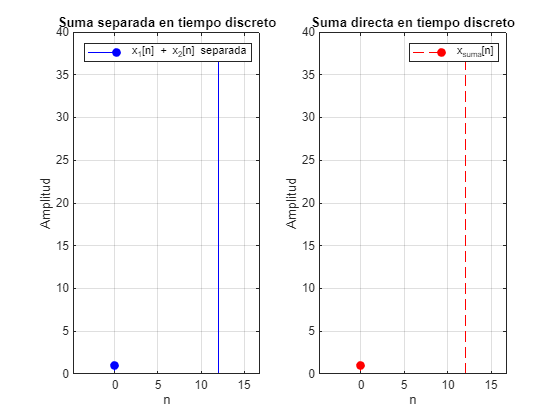


figure(4); % Figura única para este código

% Gráfica 1: Separados
subplot(1, 2, 1);
stem(n_values, double(sum_separadas_values), 'b', 'filled', 'DisplayName', 'x_1[n] + x_2[n] separada');
title('Suma separada en tiempo discreto');
xlabel('n'); ylabel('Amplitud'); grid on; legend;

% Gráfica 2: Unidos
subplot(1, 2, 2);
stem(n_values, double(sum_directa_values), 'r--', 'filled', 'DisplayName', 'x_{suma}[n]');
title('Suma directa en tiempo discreto');
xlabel('n'); ylabel('Amplitud'); grid on; legend;